A = [0, 0, 0, 1, 0, 0; 0, 0, 0, 0, 1, 0; 0, 0, 0, 0 ,0 ,1;
     0, 0, -0.2003, -0.2003, 0, 0; 0, 0, 0.2003, 0, -0.2003, 0;
     0, 0, 0, 0, 0, -1.6129;]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0         0   -0.2003   -0.2003         0         0
         0         0    0.2003         0   -0.2003         0
         0         0         0         0         0   -1.6129



B = [0, 0; 0, 0; 0, 0; 0.9441, 0.9441; 0.9441, 0.9441; -28.7097, 28.7097;]

B =          0         0
         0         0
         0         0
    0.9441    0.9441
    0.9441    0.9441
  -28.7097   28.7097


cvx_begin
    variable P(6,6) symmetric
    A*P + P*A' - 2*B*B' <= 0
cvx_end

 
Calling SDPT3 4.0: 25 variables, 4 equality constraints
------------------------------------------------------------

 num. of constraints =  4
 dim. of linear var  = 21
 dim. of free   var  =  4 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.3e+01|6.2e+01|1.4e+06| 0.000000e+00  0.000000e+00| 0:0:01| chol  1  1 
 1|0.702|0.928|4.0e+00|4.9e+00|1.6e+05| 0.000000e+00 -1.213948e+04| 0:0:02| chol  1  1 
 2|0.953|0.926|1.8e-01|5.9e-01|1.0e+04| 0.000000e+00 -4.162457e+03| 0:0:02| chol  1  1 
 3|0.979|0.981|3.9e-03|8.5e-02|4.2e+02| 0.000000e+00 -2.737813e+02| 0:0:02| chol  1  1 
 4|0.985|0.960

P

P = 1.0e+03 *

         0         0   -0.0050   -0.0022   -0.0015    0.0008
         0         0    0.0050   -0.0015   -0.0022   -0.0008
   -0.0050    0.0050    0.0069   -0.0008    0.0008   -0.0112
   -0.0022   -0.0015   -0.0008   -0.0032   -0.0010    0.0012
   -0.0015   -0.0022    0.0008   -0.0010   -0.0032   -0.0012
    0.0008   -0.0008   -0.0112    0.0012   -0.0012   -1.0177


Since P is not Positive-Definite, we use the pole placement method to obtain the feedback gains.

rng(42)
F = place(A,B,-5*rand(1,6))

F =    -2.7894    4.3008    1.4031   -5.2719    7.5168    0.1748
   -4.5983    6.1103    2.5947   -8.9450   11.1907    0.4739


Define the MAS with the given topology:

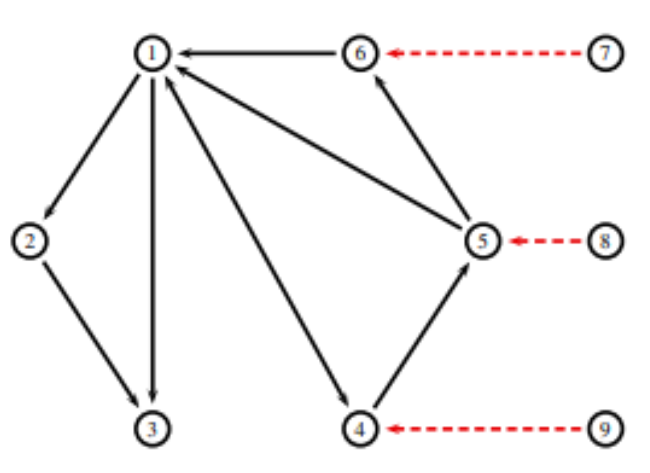

NumFollowers = 6

NumFollowers = 6

NumLeaders = 3

NumLeaders = 3

NumAgents = NumLeaders + NumFollowers

NumAgents = 9

NumStates = 6

NumStates = 6

and the Laplacian Matrices:

L_Followers = [3, 0, 0, -1, -1, -1; -1, 1, 0, 0, 0, 0;
               -1, -1, 2, 0, 0, 0; -1, 0, 0, 1, 0, 0;
               0, 0, 0, -1, 1, 0; -1, 0, 0, 0, 0, 1;]

L_Followers =      3     0     0    -1    -1    -1
    -1     1     0     0     0     0
    -1    -1     2     0     0     0
    -1     0     0     1     0     0
     0     0     0    -1     1     0
    -1     0     0     0     0     1


eigs_L = eig(L_Followers);

L_total = [3, 0, 0, -1, -1, -1, 0, 0, 0;
           -1, 1, 0, 0, 0, 0, 0, 0, 0;
           -1, -1, 2, 0, 0, 0, 0, 0, 0;
           -1, 0, 0, 2, 0, 0, 0, 0, -1;
            0, 0, 0, -1, 2, 0, 0, -1, 0;
            -1, 0, 0, 0, 0, 2, -1, 0, 0;
            0, 0, 0, 0, 0, 0, 0, 0, 0;
            0, 0, 0, 0, 0, 0, 0, 0, 0;
            0, 0, 0, 0, 0, 0, 0, 0, 0;]

L_total =      3     0     0    -1    -1    -1     0     0     0
    -1     1     0     0     0     0     0     0     0
    -1    -1     2     0     0     0     0     0     0
    -1     0     0     2     0     0     0     0    -1
     0     0     0    -1     2     0     0    -1     0
    -1     0     0     0     0     2    -1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


indx = find(round(eigs_L, 4) > 0);
lambda_min = min(real(eigs_L(indx)))

lambda_min = 1

c_th = 1/lambda_min

c_th = 1

c = c_th*1.5

c = 1.5000

Define the MAS and agents' dynamics and the initial condiitons. 

agents = repmat(struct("x_dot", [], "x", []), NumFollowers, 1);
for agent=1:NumFollowers
    agents(agent).x = rand(6,1)*2
    agents(agent).x_dot = zeros(6,1)
end

agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x


agents = 6×1 struct array with fields:
    x_dot
    x



agents(7).x = [1,0,1,0,1,0]'

agents = 7×1 struct array with fields:
    x_dot
    x


agents(8).x = [0,1,0,1,0,1]'

agents = 8×1 struct array with fields:
    x_dot
    x


agents(9).x = [1,1,1,1,1,1]'

agents = 9×1 struct array with fields:
    x_dot
    x



agents(7).x_dot = [0,0,0,0,0,0]'

agents = 9×1 struct array with fields:
    x_dot
    x


agents(8).x_dot = [0,0,0,0,0,0]'

agents = 9×1 struct array with fields:
    x_dot
    x


agents(9).x_dot = [0,0,0,0,0,0]'

agents = 9×1 struct array with fields:
    x_dot
    x


Put together everything and form a collective structure for the MAS dynimics.

allStates = [];
allStates_dot = [];
for agent=1:NumAgents
    allStates = [allStates; agents(agent).x];
    allStates_dot = [allStates_dot; agents(agent).x_dot];
end

All the above results are based on:

Solving the system using the Euler's method obtains the following results: